# regularizeNd can handle issues near convex hull that scatteredInterpolant can't

This example was adapted from the scatteredInterpolant examples from Mathworks.

This example shows an interpolated surface that deteriorates near the convex hull for scatteredInterpolant. regularizeNd can approximate the surface hear the convex hull without problem. Note that regularizeNd is not an interpolant. It is a fitting algorithm. The surface is an approximation and not an interpolated surface.

clc; clear; close all;

Create a sample data set that will exhibit problems near the boundary.

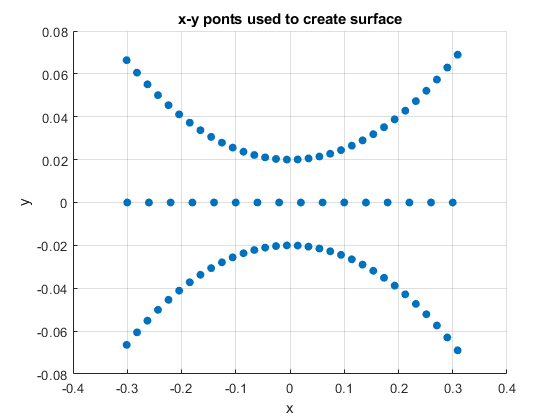

t = 0.4*pi:0.02:0.6*pi;
x1 = cos(t)';
y1 = sin(t)'-1.02;
x2 = x1;
y2 = y1*(-1);
x3 = linspace(-0.3,0.3,16)';
y3 = zeros(16,1);
x = [x1;x2;x3];
y = [y1;y2;y3];
scatter(x,y, 'filled')
xlabel('x'); ylabel('y');
grid on;
title('x-y ponts used to create surface');

Now lift these sample points onto the surface $z = x^{2}+y^{2}$ and interpolate the surface.

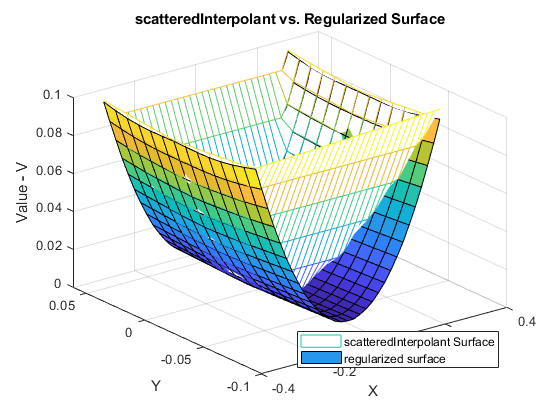

z = x.^2 + y.^2;
F = scatteredInterpolant(x,y,z);

[xi,yi] = ndgrid(-0.3:.02:0.3, -0.0688:0.01:0.0688);

xGrid = {linspace(min(x)-eps(min(x)), max(x)+eps(max(x)), 20), linspace(min(y)-eps(min(y)), max(y)+eps(max(y)), 21)};
zGrid = regularizeNd([x,y], z, xGrid, [0.001, 0.005], 'linear');
F2 = griddedInterpolant(xGrid, zGrid, 'linear');

zi = F(xi,yi);
zi2 = F2(xi,yi);

figure;
mesh(xi,yi,zi)
hold all
surf(xi,yi, zi2)
xlabel('X','fontweight','b'), ylabel('Y','fontweight','b') 
zlabel('Value - V','fontweight','b')
title('scatteredInterpolant vs. Regularized Surface');
legend({'scatteredInterpolant Surface', 'regularized surface'}, 'location', 'best')

The actual surface is:

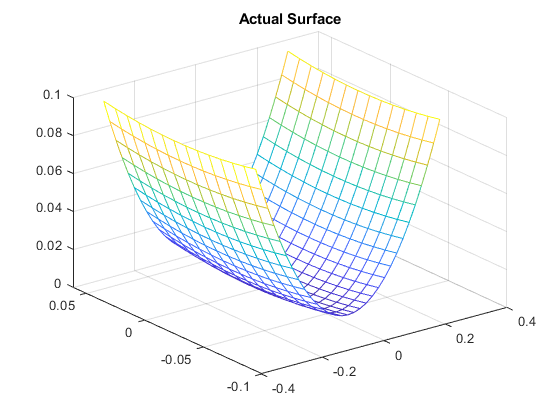

zi = xi.^2 + yi.^2;
figure
mesh(xi,yi,zi)
title('Actual Surface')

To understand why the interpolating surface deteriorates near the boundary, it is helpful to look at the underlying triangulation:

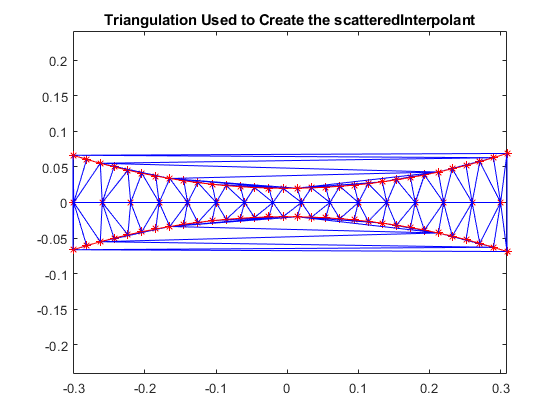

dt = delaunayTriangulation(x,y);
figure
plot(x,y,'*r')
axis equal
hold on
triplot(dt)
plot(x1,y1,'-r')
plot(x2,y2,'-r')
title('Triangulation Used to Create the scatteredInterpolant')
hold off

The triangles within the red boundaries are relatively well shaped; they are constructed from points that are in close proximity and the interpolation works well in this region. Outside the red boundary, the triangles are sliver-like and connect points that are remote from each other. There is not sufficient sampling to accurately capture the surface, so it is not surprising that the results in these regions are poor. In 3-D, visual inspection of the triangulation gets a bit trickier, but looking at the point distribution can often help illustrate potential problems.